# Using Optical Flow to Detect Motion

In the "Applying Optical Flow" video, you saw how to detect and determine the direction and magnitude of motion using optical flow. This reading contains the code workflow used in the video. Additionally, you'll use image processing to isolate the moving components of each frame. We recommend working through the script section by section to gain a better understanding of each step of the workflow.

**Note**: Running this script will write a new video file to your current folder.

## Apply Optical Flow in Sample Frame

When applying optical flow, it's a good idea to start with just a few frames to get a sense of the motion in the video and choose appropriate parameters. 

### Create Video Reader Object

Read in the bicep curl video shown in the "Applying Optical Flow" video as a video reader object.

vid = VideoReader("bicepCurls.mp4");         

### Create Optical Flow Solver

Using the Farneback method, create a solver for the optical flow equation:

of = opticalFlowFarneback;

### Plot Optical Flow Vectors

Select a frame to apply the optical flow solver to. In this case, the first frame of the video has been chosen. 

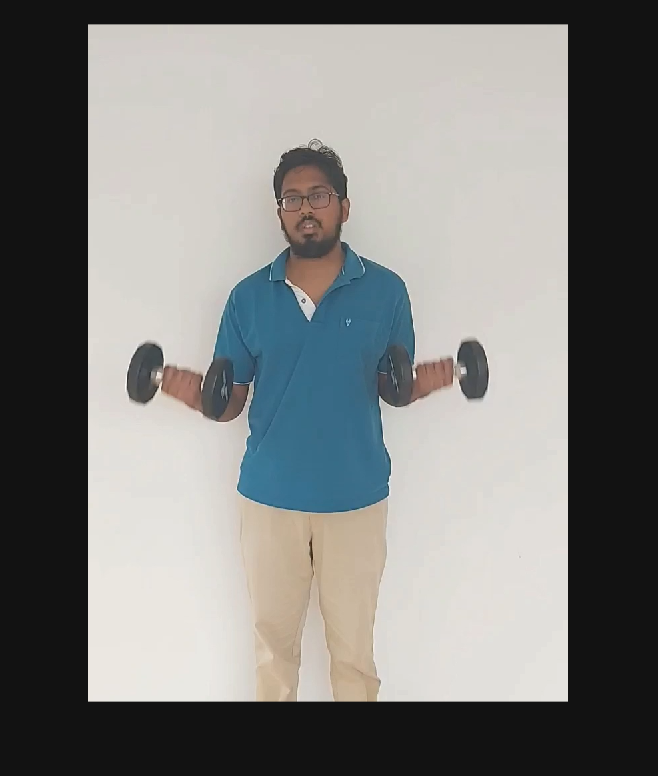

testFrame = read(vid,1);
imshow(testFrame)

Initialize the optical flow solver using this test frame. The first time the optical flow solver is called, it compares the image to an all-black background. Thus, you can ignore the output returned from the first call to the `estimateFlow` function.

estimateFlow(of,im2gray(testFrame));

Calculate the optical flow based on differences between the initial test frame and the subsequent frame to estimate a velocity vector for every pixel.

nextFrame = read(vid,2);
testFlow = estimateFlow(of,im2gray(nextFrame))

testFlow =   opticalFlow with properties:

             Vx: [1016×720 single]
             Vy: [1016×720 single]
    Orientation: [1016×720 single]
      Magnitude: [1016×720 single]


The flow variable is of data type `opticalFlow` and contains the following information for each pixel:

-     $V_x$ - the velocity of each pixel's optical flow in the *x* direction 

-     $V_y$ - the velocity of each pixel's optical flow in the y direction

-     $\textrm{Orientation}$ - the direction of each pixel's optical flow

-     $\textrm{Magnitude}$ - the magnitude of each pixel's optical flow

Plot the optical flow vectors. `"DecimationFactor"` and `"ScaleFactor"`  determine how the flow vectors are displayed. The values you use will depend on the image resolution, degree of motion, and application. Feel free to experiment with different values.

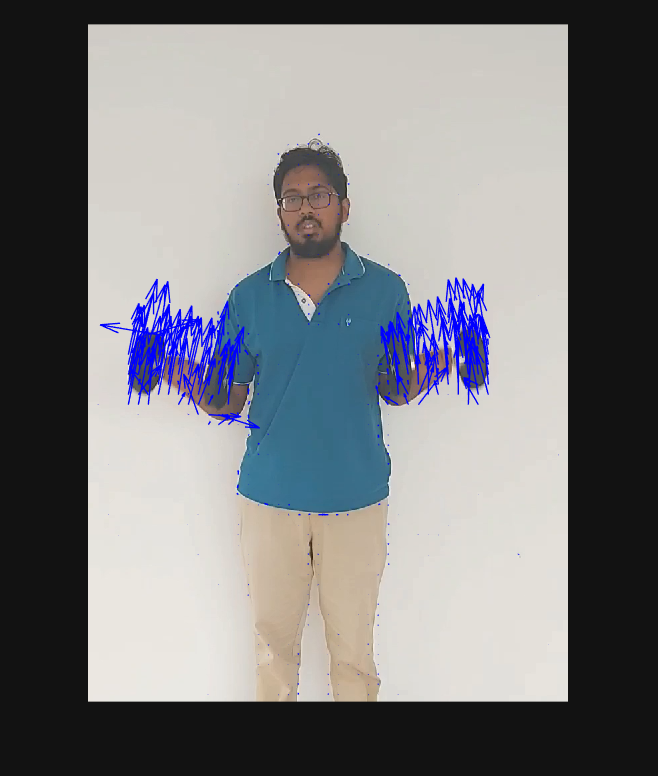

imshow(nextFrame)
hold on
plot(testFlow,"DecimationFactor",[15 15],"ScaleFactor",5)
hold off

### Thresholding Optical Flow Vectors

You can see from the above image some noise is present, displaying flow vectors on the mostly-stationary legs and wall. Set a threshold for flow magnitude to display only values above the threshold. Try experimenting with different thresholds to examine their effects.

Use the slider to try different threshold values. 

magThresh = 5;
threshFlow = testFlow.Magnitude >= magThresh;

Assign all vx and vy values below the threshold to zero.

VxThresh = testFlow.Vx;
VxThresh(~threshFlow) = 0;

VyThresh = testFlow.Vy;
VyThresh(~threshFlow) = 0;

Create a new, thresholded optical flow object.

magThreshFlow = opticalFlow(VxThresh,VyThresh);

Plot the thresholded optical flow vectors

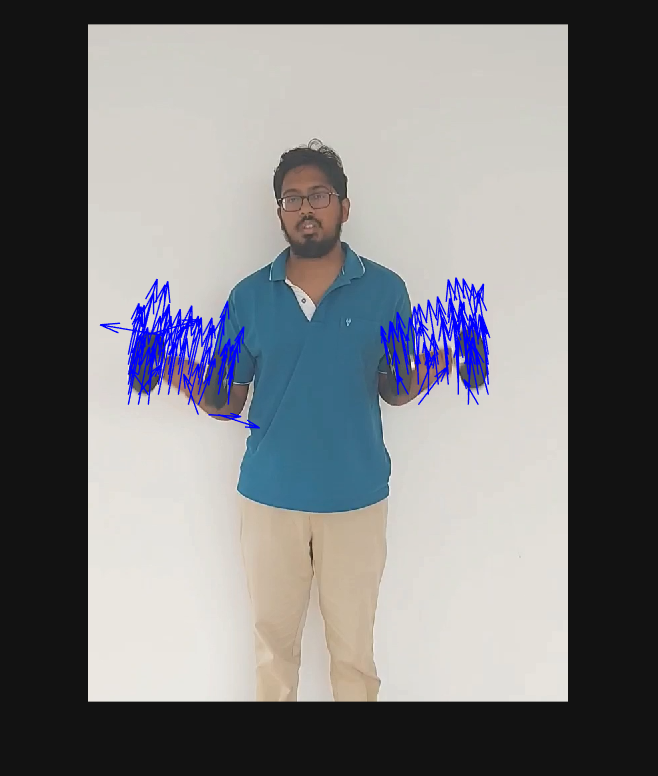

imshow(nextFrame)
hold on
plot(magThreshFlow,"DecimationFactor",[15 15],"ScaleFactor",5)
hold off

## Detect Moving Objects

Now that you have had a chance to experiment with displaying optical flow, you'll create a labeled video showing only objects with relatively high average flow magnitude, or speed.

### Initialize Optical Flow

Create a VideoWriter object for the new video.

vidOut = VideoWriter("bicepCurlsLabeled");

Read a baseline frame. Remember that you can disregard optical flow vectors returned after the first call to `estimateFlow`

of = opticalFlowFarneback;
frame = read(vid,1);
estimateFlow(of,im2gray(frame));

### Detect Moving Components

Compare next frame to baseline to calculate optical flow

frame = read(vid,2);
flow = estimateFlow(of,im2gray(frame)); 

### Refine Motion Mask

Create a mask including only parts of the image with a flow magnitude above a threshold. Here, we set it back to 5 so the image processing steps below will work. If you experiment with the threshold, you may need to adjust how you refine the mask.

magThresh = 5;
mask = (flow.Magnitude > magThresh);

Apply mask to all color spaces.

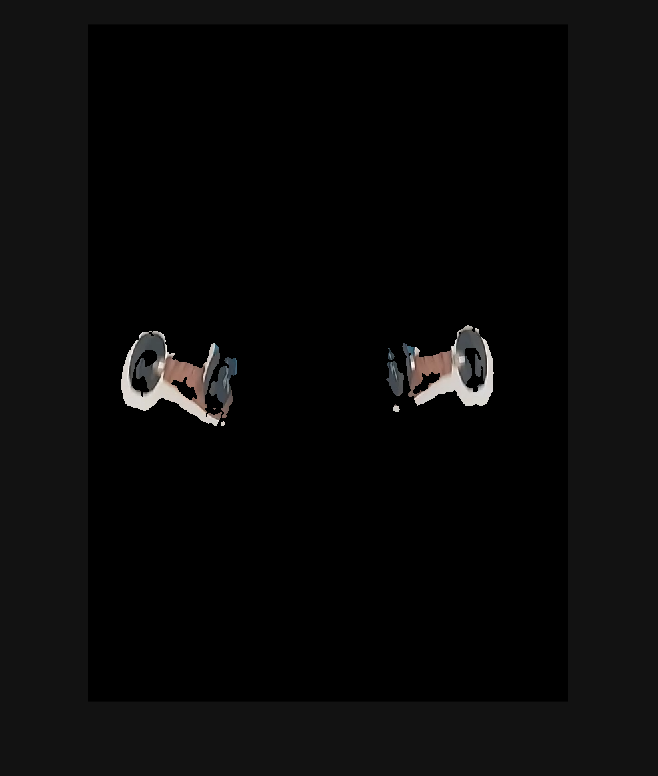

maskedFrame = frame;
maskedFrame(repmat(~mask,[1 1 3])) = 0;
imshow(maskedFrame)

You can see that there are some holes in the mask, especially large areas of similar colors (such as on the lifter's forearms), where the algorithm was unable to distinguish pixel motion from frame to frame. To improve the mask, use image processing to remove unwanted noise and smooth errors in the image. Here, we

- perform morphological operations to remove noise and close holes

- remove regions less than 800 pixels in size

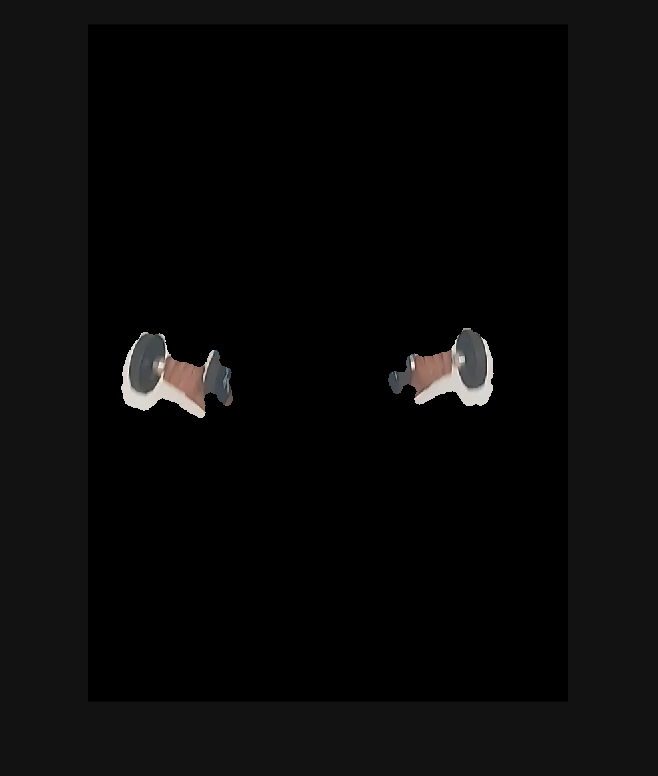

se = strel("disk",8,0);
mask = imopen(mask,se);
mask = imclose(mask,se);
mask = imfill(mask,"holes");

% Keep only larger regions
mask = bwareafilt(mask,[800, Inf]);

% Apply mask to all color spaces
maskedFrame = frame;
maskedFrame(repmat(~mask,[1 1 3])) = 0;
imshow(maskedFrame)

## Calculate Object Speed

In many applications, you need the average speed of a moving object. You calculate the mean velocity magnitude for each object using `regionprops`, returning `"MeanIntensity"` for a given region. A bounding box is added to the frame and labeled with the mean intensity.

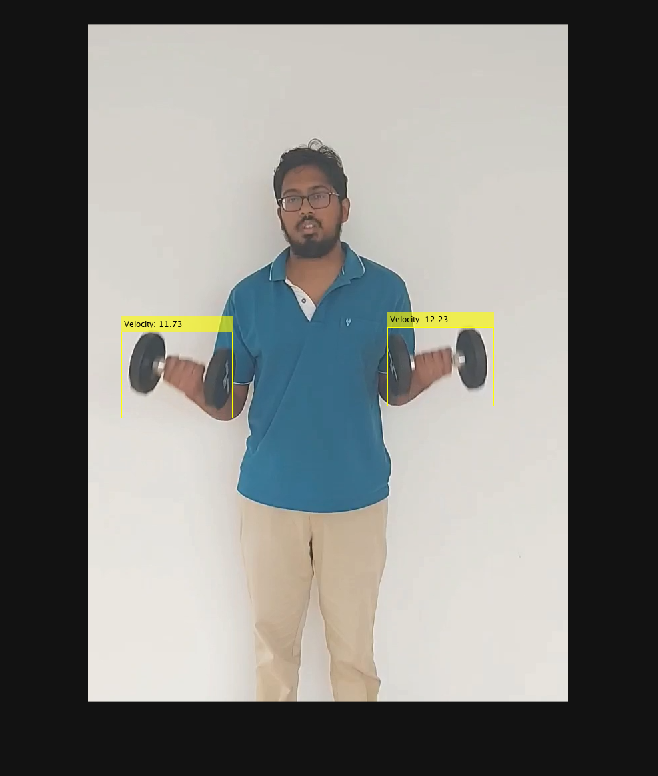

movObjs = regionprops("table",mask,flow.Magnitude,["MeanIntensity","BoundingBox"]);

if ~isempty(movObjs)
    labelFrame = insertObjectAnnotation(frame,"rectangle",movObjs.BoundingBox,...
        "Velocity: " + string(round(movObjs.MeanIntensity,2)));
end
imshow(labelFrame)

## Apply to Each Frame

**Note**: Running this section will add a new video file to your current folder.

Once you are happy with the results, you can create can repeat the process for each frame and save the result as a new video.

Open the VideoWriter object and write frame 2 to the file.

open(vidOut)
writeVideo(vidOut, labelFrame)

Repeat for the remaining frames in the video. This may take a few minutes. 

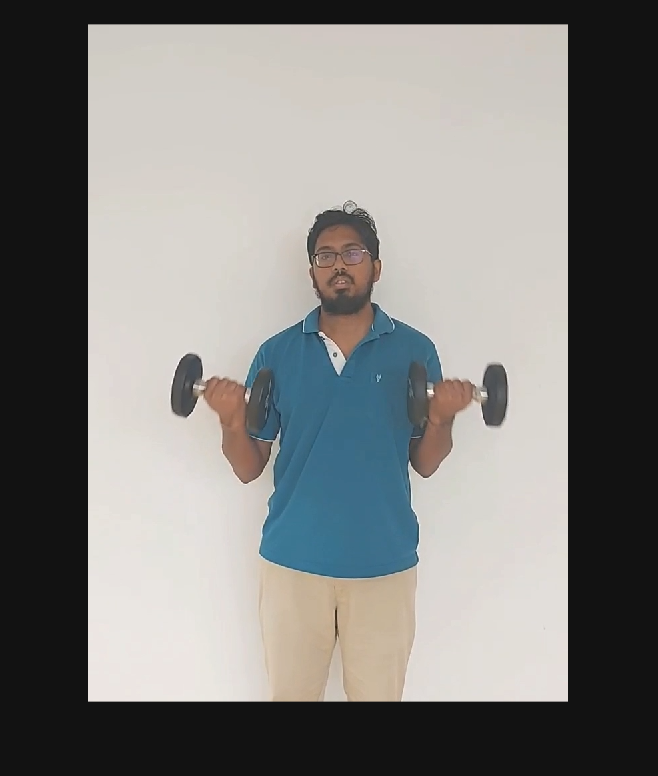

for ii = 3:vid.NumFrames
    frame = read(vid,ii);
    flow = estimateFlow(of,im2gray(frame));
    
    % Create the mask for pixels with high optical flow magnitude values
    mask = flow.Magnitude > magThresh;

    % Performing morphological operations to smooth the mask:
    se = strel("disk",8,0);
    mask = imopen(mask,se);
    mask = imclose(mask,se);
    mask = imfill(mask,"holes");
    
    % Keep only larger regions of the mask:
    mask = bwareafilt(mask,[800, Inf]);

    % Create magnitude labels
    movObjs = regionprops("table",mask,flow.Magnitude,"MeanIntensity","BoundingBox");

    % Remove objects moving (on average) below the threshold speed
    movObjs(movObjs.MeanIntensity < magThresh,:) = [];

    % Label objects moving sufficiently fast
    if ~isempty(movObjs)
        labelFrame = insertObjectAnnotation(frame,"rectangle",movObjs.BoundingBox,...
        "Velocity: " + string(round(movObjs.MeanIntensity,2)));
    end

    % Write new masked frame to video
    imshow(labelFrame)
    imshow(frame)
    writeVideo(vidOut,labelFrame)
end

Close the VideoWriter Object

close(vidOut);

### View the Final Video

How well did optical flow do at identifying the moving parts of the image? Try out the approach with one of your own videos.

implay("bicepCurlsLabeled.avi")

*Copyright 2025 The MathWorks, Inc.*